# splWindows

A script to calculate a lobing pattern of tonal and broadband sound pressure level measurements at an array of hydrophones from a passing ship using its AIS track. By grouping all of the consecutive measurements along the ships track by same look angle (azimuth), the lobing characteristics of the ship's noise signature can be estimated. 

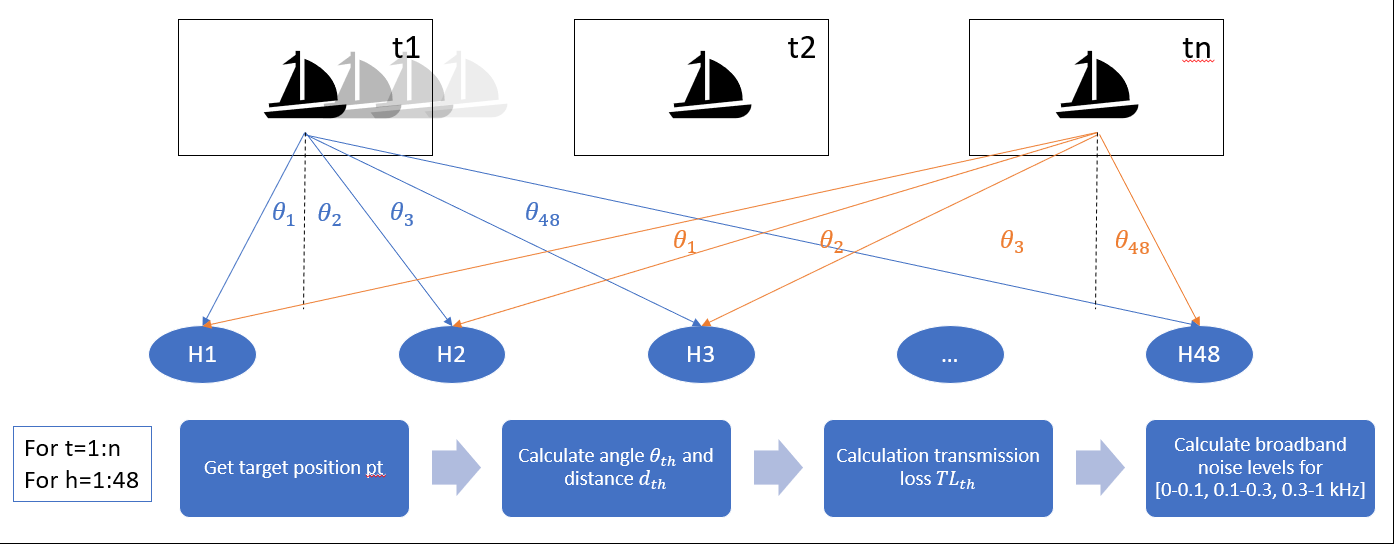

## Initialize & set parameters

clearvars
load arrays_lat-long
array1=table2array(array1(:,1:2));
array2=table2array(array2(:,1:2));

## Load AIS file

m = matfile('byShip.mat');
AIS = m.Heb_Sky;
%load byShip.mat
%AIS = Heb_Sky;   %select ship of interest
AIS = sortrows(AIS,'datetime','ascend');
AIS(1:793,:) = [];  % need to find a way to filter out by +/- CPA time  --> 26-Aug-2015 17:30:00 
AIS(330:end,:) = [];  % probably timetable is the answer
AIStime = table2timetable(AIS);  % might need to make all of this a structure

## Calculate ranges along ship track

[R1,R2] = calcDist(AIS.lat, AIS.long, array1, array2);
AIStime.R1 = R1(:,1,1); AIStime.R2 = R2(:,1,1);  %cut out this step and move up
AIStime.theta1 = R1(:,1,2); AIStime.theta2 = R2(:,1,2);  %cut out this step and move up

### Calculate CPA range and time

%rangeCPA_1 = min(R1(:,1,1));
%rangeCPA_2 = min(R2(:,1,1));
[rangeCPA_1,timeCPA_1] = min(R1(:,1,1));
[rangeCPA_2,timeCPA_2] = min(R2(:,1,1));
formatSpec = 'CPA range AAA1 = %4.2f km and AAA2 = %4.2f km';
fprintf(formatSpec,rangeCPA_1,rangeCPA_2);  %can put CPA time by indexing to timetable--shuffle up to automated (10)

CPA range AAA1 = 0.42 km and AAA2 = 1.51 km

### Plot bearing histogram of ranges

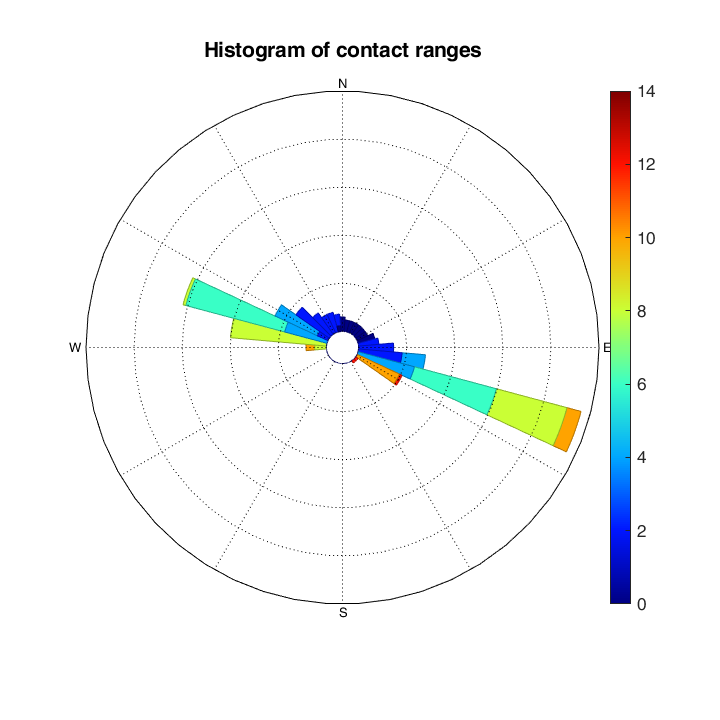

rangeRoser(R2(:,1,2), R2(:,1,1), 'legendtype', 1, 'anglenorth', 0, 'angleeast', 90, 'lablegend', 'Distance (km)');
set(gca,'FontSize',14);

### Plot time resolution of AIS data, speed and range history of contact

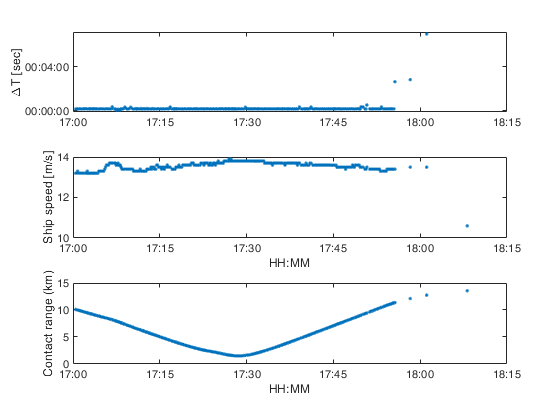

figure
subplot(3,1,1)
    plot(AIS.datetime(1:end-1),diff(AIS.datetime),'.');
    datetick('x')
    ylabel('\DeltaT [sec]')    
subplot(3,1,2)
    plot(AIS.datetime,AIS.speed_over_ground,'.');
    datetick('x')
    ylabel('Ship speed [m/s]')
    xlabel('HH:MM')    
subplot(3,1,3)
    plot(AIS.datetime,R2(:,1,1),'.');
    datetick('x')
    ylabel('Contact range (km)')
    xlabel('HH:MM')    

## Calculate TL for each window location

%TL1 = 10*log(R1(:,1,1)*1000);
AIStime.TL2 = 6*log(R2(:,1,1)*1000);   %for first hph location only (24 for centre)
%TL2 = range2tl(R2,700,100);

## Load acoustic data

multi = 'singleCh.wav';           % Select the 48-ch (allCh) or 1-ch (singleCh) file
NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\HebSky\proc',multi);
[x,fs] = audioread(NWFile);

## Downsample acoustic data

nFactor = 100;
y = downsample(x,nFactor); %downsample or decimate?
x = y; 

## Generate time vector

t = cumsum(ones(size(x(:,1)))/fs); % time vector in seconds
t = seconds(t*nFactor);
startTime = datetime(2015,8,26,16,59,58);  % west_aaa2_20150826_165958_00_0131
t = t + startTime;

### Calculate Received SPL

windowSize = 10;
gain = 62;   % Amplifier gain 70 dB (adjustable), A/D -8 dB
RL2 = gain + spl(x,'water',windowSize,fs);     % calculate SPL using spl sub-routine with 1-sec windows re 1uPa
RLtime = array2timetable(RL2,'RowTimes',t);   %could shorten this 

### Plot signal and SPL

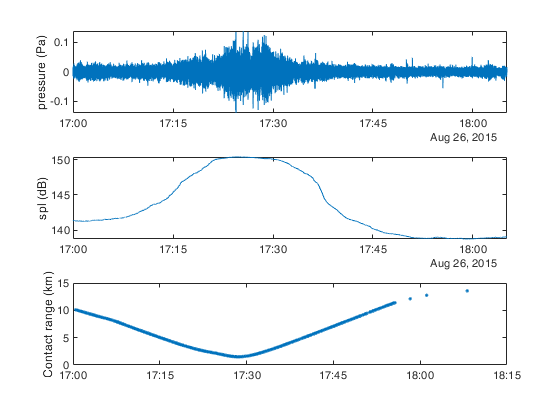

figure
subplot(3,1,1)
    plot(t,x)
    axis tight
    ylabel('pressure (Pa)')
subplot(3,1,2)
    plot(t,RL2)
    axis tight
    ylabel('spl (dB re 1 \muPa^2)')
subplot(3,1,3)
    plot(AIS.datetime,R2(:,1,1),'.');
    datetick('x')
    ylabel('Contact range (km)')   

## Calculate lobing pattern

Make RL and TL same length and combine in time 

SPL = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(30));

#### Solve sonar equation

SPL.SL2 = SPL.RL2 - SPL.TL2;

#### Determine look angle (aspect)

SPL.aspect2 = SPL.hdg - SPL.theta2;
SPL.rads2 = deg2rad(SPL.aspect2);

### Plot lobing pattern

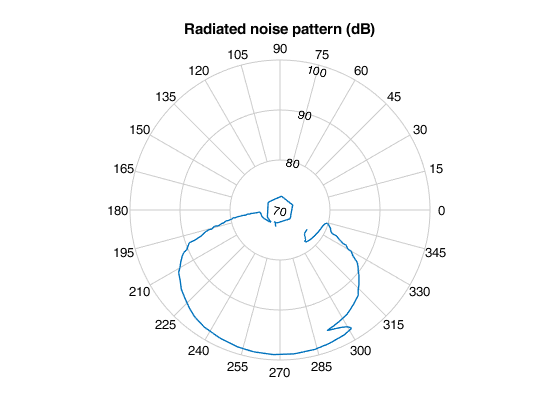

figure
%polarpattern(SPL.aspect2,SPL.SL2, ...

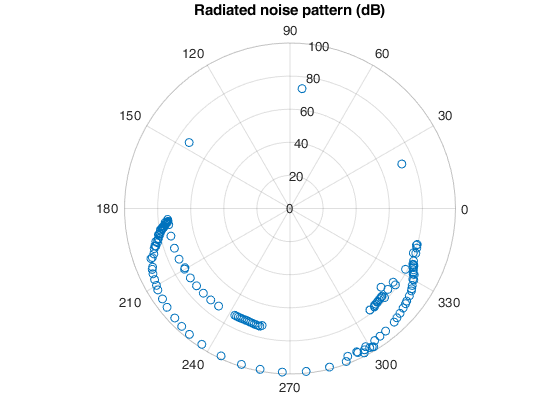

    %'TitleTop', 'Broadband (10 - 2500 Hz) radiated noise pattern (dB re 1\muPa @ 1m )')
figure
polarscatter(SPL.rads2,SPL.SL2)
title('Broadband (10 - 2500 Hz) radiated noise pattern (dB re 1\muPa @ 1m )')